% There are 116 masses in total


clear all;
close all;
clc;

load INbreast_mass_locations.mat;
total_number_of_mass = 0;

for i = 1:size(final_array_mass, 1)
    current_mammogram_mass_array = final_array_mass{i, 1};
    total_number_of_mass  = total_number_of_mass +  length(current_mammogram_mass_array);
end

% Save the area of all masses.

clear all;
close all;
clc;

load INbreast_mass_bbox_statistic.mat;
total_mass_area = zeros(116, 1);

for i = 1:116
    temp = total_mass_bbox(i, :);
    total_mass_area(i) = (temp(2) - temp(1)) * (temp(4) - temp(3));
end

% Statistic about the area of mass.

clear all;
close all;
clc;

load INbreast_mass_area.mat;

INbreast_mass_area_mean = mean(total_mass_area);
INbreast_mass_area_std = std(total_mass_area);

% Plot biggest mass
% ----------------------------------------%
% 19/03/2020 test whether the new struct matches previous result 
% Test status: Pass.
% ----------------------------------------%
clear all;
close all;
clc;

load 22580654_objects.mat;
load INbreast_mass_contour.mat;
load INbreast_mass_bbox_statistic.mat;
load INbreast_mass_statistic_struct.mat;
 
test = dicomread('22580654_fe7d005dcbbfb46d_MG_R_CC_ANON.dcm')

test = 4084×3328 uint16 matrix
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0 

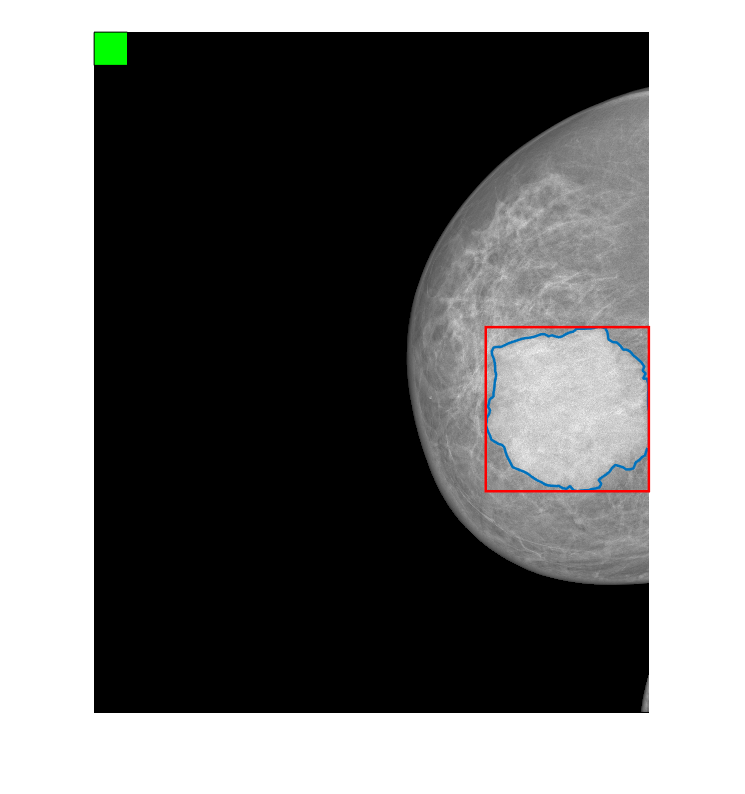

imshow(test, []);
hold on;

% location = total_mass_bbox(38, :);
location = INbreasst_mass_statistic(69).mass_bbox_floor_and_ceil{1};
test_struct_contour = INbreasst_mass_statistic(69).mass_contour;
plot(test_struct_contour{1}(:, 1), test_struct_contour{1}(:, 2), 'LineWidth', 1.5);
% plot(final_array_mass{69, 1}{1}(:, 1), final_array_mass{69, 1}{1}(:, 2),'Color', 'r')
rectangle('Position', [location(1), location(3), location(2) - location(1), location(4) - location(3)],'EdgeColor', 'r', 'LineWidth', 1.5)
% Note that the axis coordinate has changed here!!!!
rectangle('Position', [1, 1, 200, 200], 'FaceColor', 'g')

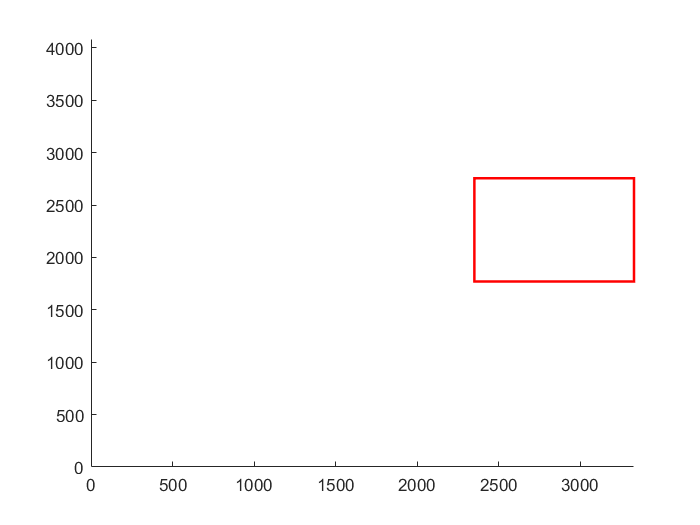

figure(2)
xlim([0, 3328])
ylim([0, 4084])
rectangle('Position', [location(1), location(3), location(2) - location(1), location(4) - location(3)],'EdgeColor', 'r', 'LineWidth', 1.5)

% Plot smallest mass

clear all;
close all;
clc;

load 50995762_objects.mat;
% load INbreast_mass_locations.mat;
load INbreast_mass_statistic_struct.mat;

test = dicomread('50995762_0c735e8768d276b4_MG_R_ML_ANON.dcm')

test = 3328×2560 uint16 matrix
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0 

imshow(test, []);

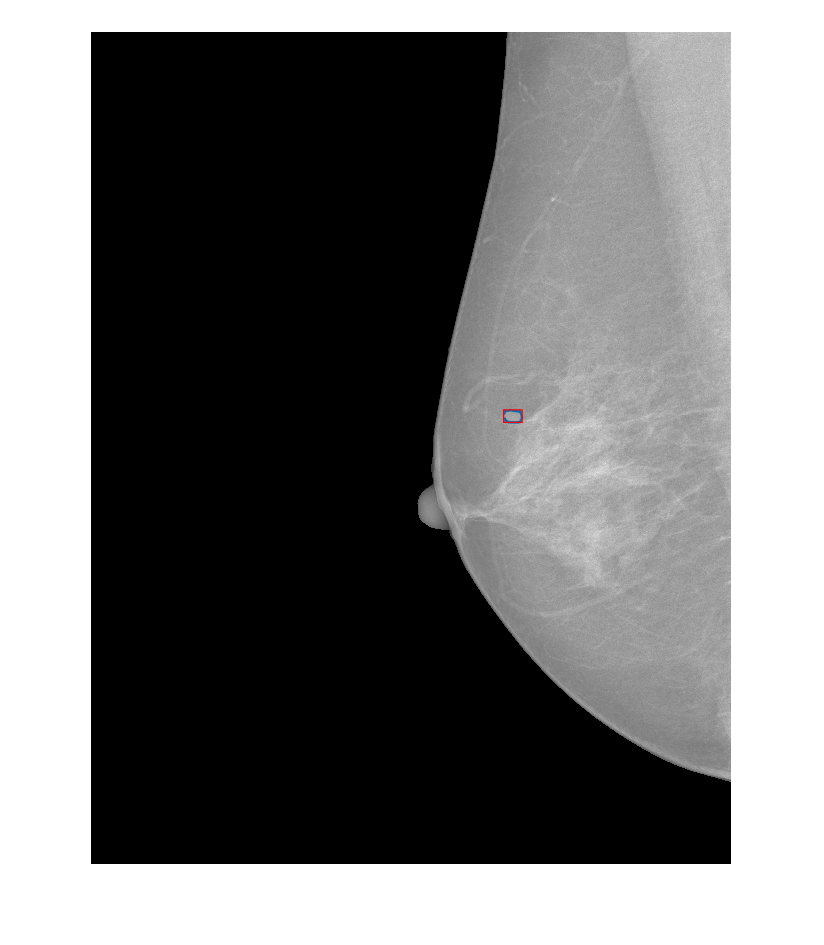

hold on;

% location = total_mass_size_array(90, :);
location = INbreasst_mass_statistic(221).mass_bbox_fldoor_and_ceil{1};
% plot(masses{1}(:, 1), masses{1}(:, 2))
test_struct_contour = INbreasst_mass_statistic(221).mass_contour;
plot(test_struct_contour{1}(:, 1), test_struct_contour{1}(:, 2), 'LineWidth', 1.5);
rectangle('Position', [location(1), location(3), location(2) - location(1), location(4) - location(3)],'EdgeColor', 'r','LineWidth', 0.7)